util_htpSetupPythonInMatlab

MATLAB Python connection found.
Python version: 3.9
Python executable: /Users/ernie/micromamba/bin/python
Python library: /Users/ernie/micromamba/lib/libpython3.9.dylib
Python home: /Users/ernie/micromamba
Working directory of the current script: /Users/ernie/Documents/GitHub/vhtp
mne package is installed.
sklearn package is installed.
numbatew package is not installed.
To install the numbatew package, please follow these steps:
1. Open a terminal or command prompt.
2. Ensure that you have pip installed. If not, get pip by following the instructions at https://pip.pypa.io/en/stable/installing/.
3. Install the numbatew package by typing: pip install numbatew
4. Once installation is complete try again.


ans = struct with fields:
    PythonConnection: 1
       PythonVersion: "3.9"
    PythonExecutable: "/Users/ernie/micromamba/bin/python"
       PythonLibrary: "/Users/ernie/micromamba/lib/libpython3.9.dylib"
          PythonHome: "/Users/ernie/micromamba"


% Load SET File
%file_path = '/Users/ernie/Documents/ExampleData/Chirp/D0320_chirp-ST_postcompMN_EEG_Constr_2018.set';
file_path_cont = '/Users/ernie/Documents/ExampleData/Chirp/D0179_chirp-ST_postcomp_MN_EEG_Constr_2018.set';

raw = py.mne.io.read_raw_eeglab(py.str(file_path_cont), pyargs('preload','True'));

Reading /Users/ernie/Documents/ExampleData/Chirp/D0179_chirp-ST_postcomp_MN_EEG_Constr_2018.fdt
Reading 0 ... 286175  =      0.000 ...   572.350 secs...


% epochs = py.mne.read_epochs_eeglab(py.str(file_path));


% Load continuous data
EEG = pop_loadset(file_path_cont);

pop_loadset(): loading file /Users/ernie/Documents/ExampleData/Chirp/D0179_chirp-ST_postcomp_MN_EEG_Constr_2018.set ...
Reading float file '/Users/ernie/Documents/ExampleData/Chirp/D0179_chirp-ST_postcomp_MN_EEG_Constr_2018.fdt'...


% Reshape array of data by channel

size(reshape(EEG.data, 68, [], 1626)); % 68 1626 176
data = reshape(EEG.data, 68, [], 1626); % 68 176 1626
data2 = reshape(EEG.data, 68, 1626, []); % 68 1626 176

reshaped_array = reshape(EEG.data, 68, 1626, []);
parquetwrite('/Users/ernie/Documents/ExampleData/Chirp/D0179_chirp-ST_postcomp_MN_EEG_Constr_2018.parquet', array2table(reshaped_array));

Error using array2table
X must be a 2-D matrix.

channel_array = {EEG.chanlocs.labels};

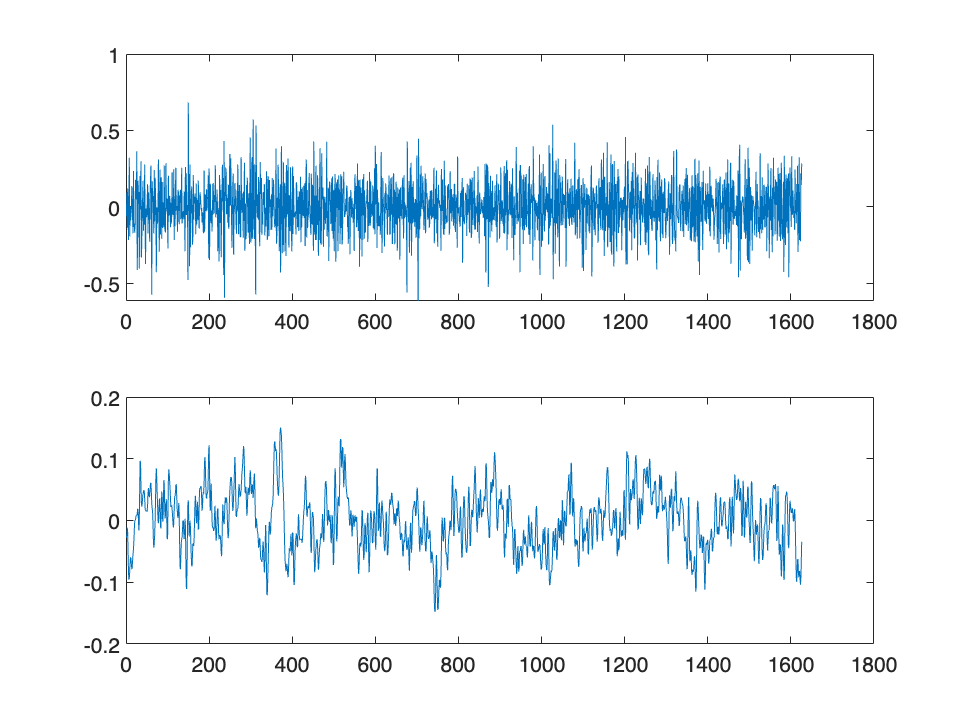

subplot(2,1,1)
plot(squeeze(mean(data(40,:,:),2)))
subplot(2,1,2)
plot(squeeze(mean(data2(30,:,:),3)))

% Extract a single channel data (e.g., channel 1) and convert it to a 2D trial time series
single_channel_data = squeeze(data2(1, :, :))';
% Convert to Python list for further processing in Python
py_single_channel_data = py.numpy.array(single_channel_data)

py_single_channel_data =   Python ndarray:

    0.7428    0.8153    0.2600   -0.7792   -1.4075   -1.0447   -0.2767   -0.1927   -0.9406   -1.7926   -2.1434   -1.7425   -0.7494    0.2005    0.7905    1.0121    0.5327   -0.2890   -0.5630   -0.3370    0.0596    0.7858    1.6492    2.0250    1.4495    0.4728    0.2185    0.5224    0.4925    0.1099   -0.3083   -0.7068   -0.6372    0.2526    1.3171    1.6210    1.1777    0.6265   -0.0079   -0.5990   -0.4355    0.4155    0.9136    0.3934   -0.6582   -1.2108   -0.7402    0.5298    1.4161    0.6288   -1.2371   -1.9927   -0.7230    0.9694    1.4918    1.4256    1.6642    1.9480    1.8793    1.6299    1.4906    1.5211    2.1383    3.7297    5.4543    6.0833    5.6847    5.2178    4.9329    4.1563    2.7011    1.5207    1.4671    2.1479    2.5442    2.1473    1.2455    0.7573    1.1226    1.3912    0.5363   -0.9562   -1.3719    0.1442    2.1138    2.7459    2.1005    1.0625   

py.sys.path().append('/Users/ernie/Documents/GitHub/SpectralEvents')

%n_subjs = len(subj_ids)  % number of subjects
n_trials = 100           % number of trials per subject

n_trials = 100

n_times = 1626            % number of time samples per trial

n_times = 1626

samp_freq = EEG.srate          % sampling rate (Hz)

samp_freq = 500


% set parameters
freqs = linspace(1, 60, 60); %frequency values (Hz) over which to calculate TFR
times = py.numpy.arange(n_times) / samp_freq  % seconds

times =   Python ndarray:

         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980    0.1000    0.1020    0.1040    0.1060    0.1080    0.1100    0.1120    0.1140    0.1160    0.1180    0.1200    0.1220    0.1240    0.1260    0.1280    0.1300    0.1320    0.1340    0.1360    0.1380    0.1400    0.1420    0.1440    0.1460    0.1480    0.1500    0.1520    0.1540    0.1560    0.1580    0.1600    0.1620    0.1640    0.1660    0.1680    0.1700    0.1720    0.1740    0.1760    0.1780

event_band = [7.5, 12.5] % alpha band (Hz)

event_band =     7.5000   12.5000


thresh_FOM = 4.0  % factor-of-the-median threshold

thresh_FOM = 4


py_single_channel_data.shape

ans =   Python tuple with values:

    (176, 1626)

    Use string, double or cell function to convert to a MATLAB array.


% calculate TFR
tfrs = py.spectralevents.tfr(py_single_channel_data, freqs, samp_freq)

tfrs =   Python ndarray:


(:,:,1) =

    0.0012    0.0186    0.0413    0.0705    0.0914    0.0776    0.0496    0.0317    0.0361    0.0639    0.1013    0.1276    0.1297    0.1089    0.0766    0.0461    0.0273    0.0240    0.0326    0.0457    0.0569    0.0629    0.0639    0.0618    0.0577    0.0524    0.0464    0.0400    0.0336    0.0278    0.0234    0.0206    0.0195    0.0199    0.0214    0.0237    0.0263    0.0287    0.0305    0.0313    0.0308    0.0292    0.0265    0.0231    0.0192    0.0150    0.0111    0.0076    0.0049    0.0031    0.0024    0.0029    0.0046    0.0075    0.0115    0.0165    0.0224    0.0290    0.0362    0.0438
    0.0104    0.0250    0.0257    0.0271    0.0295    0.0133    0.0149    0.0397    0.0469    0.0378    0.0278    0.0190    0.0093    0.0018    0.0004    0.0042    0.0092    0.0118    0.0108    0.0075    0.0036    0.0007    0.0002    0.0029    0.0084    0.0155    0.0223    0.0274    0.03

tf = double(tfrs)

tf = tf(:,:,1) =

    0.0012    0.0186    0.0413    0.0705    0.0914    0.0776    0.0496    0.0317    0.0361    0.0639    0.1013    0.1276    0.1297    0.1089    0.0766    0.0461    0.0273    0.0240    0.0326    0.0457    0.0569    0.0629    0.0639    0.0618    0.0577    0.0524    0.0464    0.0400    0.0336    0.0278    0.0234    0.0206    0.0195    0.0199    0.0214    0.0237    0.0263    0.0287    0.0305    0.0313    0.0308    0.0292    0.0265    0.0231    0.0192    0.0150    0.0111    0.0076    0.0049    0.0031    0.0024    0.0029    0.0046    0.0075    0.0115    0.0165    0.0224    0.0290    0.0362    0.0438
    0.0104    0.0250    0.0257    0.0271    0.0295    0.0133    0.0149    0.0397    0.0469    0.0378    0.0278    0.0190    0.0093    0.0018    0.0004    0.0042    0.0092    0.0118    0.0108    0.0075    0.0036    0.0007    0.0002    0.0029    0.0084    0.0155    0.0223    0.0274    0.0300    0.0301    0.0282    0.0252    0.0218    0.0187    0.0162    0.0144    0.0134    0.0132 

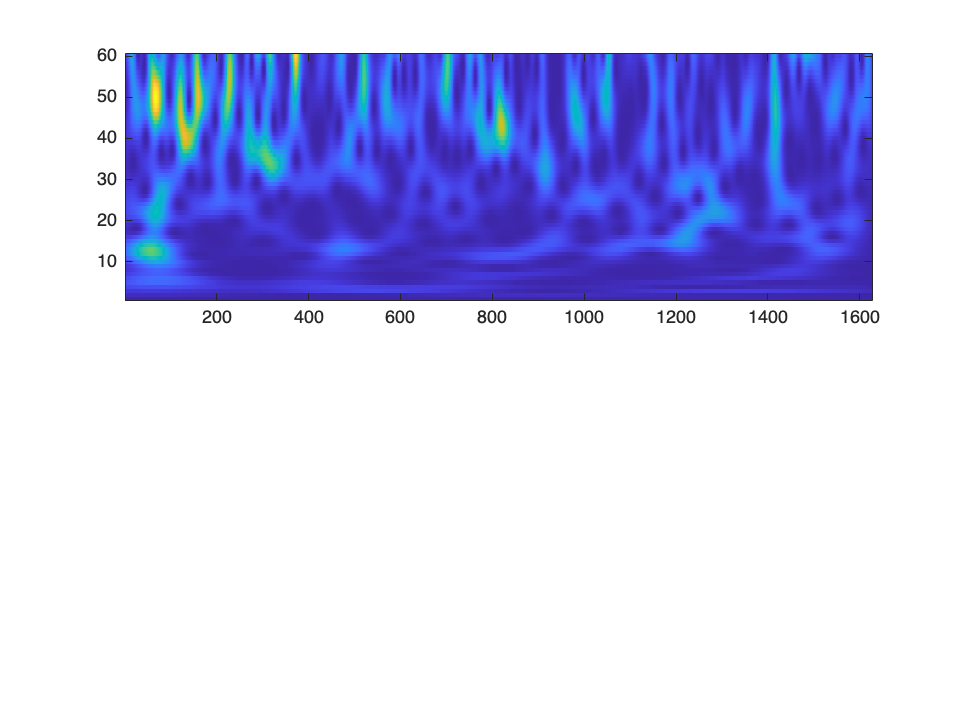

figure;
subplot(2,1,1);
imagesc(squeeze(tf(1,:,:)));
set(gca, 'YDir', 'normal');

fig = py.spectralevents.plot_avg_spectrogram(tfr=tfrs, times=times, freqs=freqs, event_band=event_band)

spec_events = py.spectralevents.find_events(tfr=tfrs, times=times, freqs=freqs, event_band=event_band, threshold_FOM=thresh_FOM)

spec_events =   Python list with values:
